We apply our control design framework to an n-dof Oscillator Chain with cubic and quadratic nonlinearities as follows.

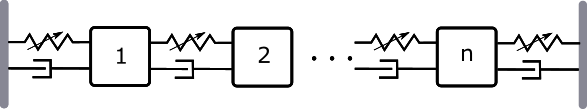

In this demo, we select n=10 and place 2 control inputs at dof-1 and dof-5, respectively.

clear all; close all; clc

## Example setup

n = 10;    % number of oscillators
mass = 1;  % mass
k = 1;     % stiffness
c = 0.1;   % damping
kappa2 = 0;   % quadratic nonlinearity
kappa3 = 0.5; % cubic nonlinearity
[K,C,f2,f3] = assemble_global_coefficients(k,kappa2,kappa3,c,n);

**Dirichlet boundary conditions**

K = K(2:n+1,2:n+1);
C = C(2:n+1,2:n+1);
M = mass*speye(n,n);
f3 = f3(2:n+1,2:n+1,2:n+1,2:n+1);

#### Dynamical System Setup

Consider the following forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}({\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}({\phi}),\\\dot{\phi}	
=\Omega$$


where 


$$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right]$$


DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',{[],f3});
set(DS.Options,'Emax',10,'Nmax',20,'notation','multiindex')
outdof = [1 5]; 
outdof = floor(outdof);
outdof = outdof(outdof>0);
set(DS.Options, 'outDOF', outdof);

**Add external forcing and also control matrix**

Bext     = zeros(n,2); Bext(1,1)=1; Bext(5,2)=1;
ExtForce = @(t) Bext*[sin(0.1*sqrt(2)*t);3*cos(0.1*sqrt(3)*t)];
epsilon  = 1e-3;
set(DS,'D',Bext,'E',ExtForce,'epsilon',epsilon);

#### Linear Modal analysis

We solve generalized eigenvalue problem


$$\mathbf{A}\mathbf{V}=\mathbf{B}\mathbf{V}\mathbf{D}$$


where $\mathbf{V}=(\mathbf{v}_1,\cdots,\mathbf{v}_n)$ and $\mathbf{D}=\mathrm{diag}\{\lambda_1,\cdots,\lambda_n\}$ such that $\mathbf{A}\mathbf{v}_i=\lambda_i\mathbf{B}\mathbf{v}_i$. We also calculate the left eigenvectors $\mathbf{W}=(\mathbf{w}_1,\cdots,\mathbf{w}_n)$ such that

$\mathbf{W}^\ast\mathbf{A}=\mathbf{D}\mathbf{W}^\ast\mathbf{B}$.

The eigenvectors are normalized in the folowing way

$\mathbf{W}^\ast\mathbf{B}\mathbf{V}=\mathbb{I}$.

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 10 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.423148e-02
modal damping ratio for 2 mode is 2.817326e-02
modal damping ratio for 3 mode is 4.154150e-02
modal damping ratio for 4 mode is 5.406408e-02
modal damping ratio for 5 mode is 6.548607e-02
modal damping ratio for 6 mode is 7.557496e-02
modal damping ratio for 7 mode is 8.412535e-02
modal damping ratio for 8 mode is 9.096320e-02
modal damping ratio for 9 mode is 9.594930e-02
modal damping ratio for 10 mode is 9.898214e-02

 The first 20 nonzero eigenvalues are given as 
  -0.0041 + 0.2846i
  -0.0041 - 0.2846i
  -0.0159 + 0.5632i
  -0.0159 - 0.5632i
  -0.0345 + 0.8301i
  -0.0345 - 0.8301i
  -0.0585 + 1.0797i
  -0.0585 - 1.0797i
  -0.0858 + 1.3069i
  -0.0858 - 1.3069i
  -0.1142 + 1.5072i
  -0.1142 - 1.5072i
  -0.1415 + 1.676

## SSM Reduced dynamics - autonomous part

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
order = 3;
% master subspace
modes = [1 2];
S.choose_E(modes);

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     1
     4     2
     5     3
     6     4
     0     2
     1     3
     2     4
     3     5
     4     6
     4     1
     5     2
     6     3
     1     4
     2     5
     3     6
These are in resonance with the follwing eigenvalues of the slave subspace
  -0.0159 + 0.5632i
  -0.0159 + 0.5632i
  -0.0159 + 0.5632i
  -0.0159 + 0.5632i
  -0.0159 + 0.5632i
  -0.0159 - 0.5632i
  -0.0159 - 0.5632i
  -0.0159 - 0.5632i
  -0.0159 - 0.5632i
  -0.0159 - 0.5632i
  -0.0345 + 0.8301i
  -0.0345 + 0.8301i
  -0.0345 + 0.8301i
  -0.0345 - 0.8301i
  -0.0345 - 0.8301i
  -0.0345 - 0.8301i
sigma_out = 48
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     1     2
     2     3
     3     4
These are in resonance with the follwing eigenvalues of the master subspace
  -0.0041 + 0.2846i
  -0.0041 + 0.2846i
  -0.0041 + 0.2846i


% compute autonomous SSM coefficients
[W_0,R_0] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.69E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.55E-02 MB


auData = construct_autoData(DS, modes, R_0);

## Linear model order reduction analysis

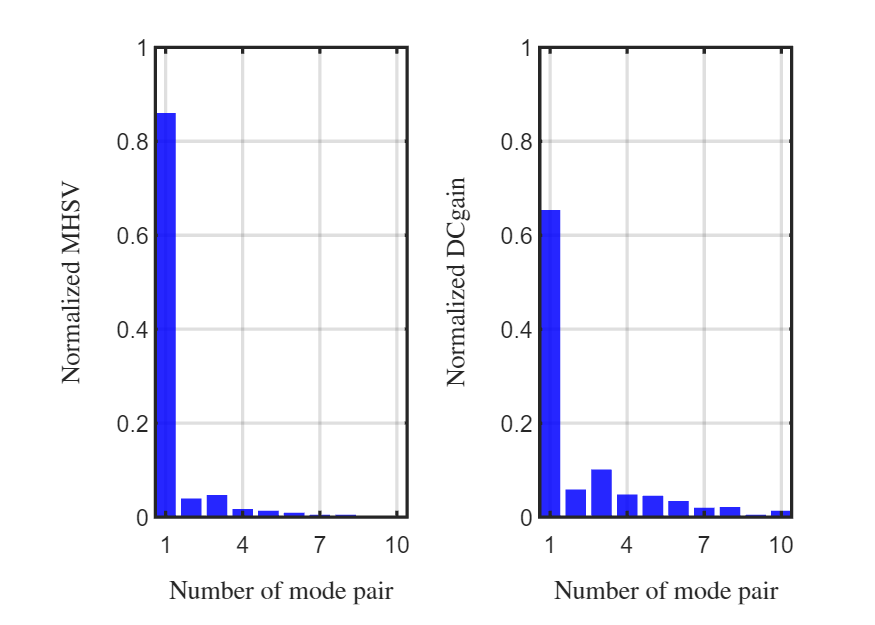

MHSV sum of the first 2 pairs
    0.9642
DCgain sum of the first 2 pairs
    0.8614


res = Linear_MOR(DS,10);

## Free vibration

% Construction of initial condition
p0 = [2.5 2.5]';
z0 = reduced_to_full(p0,W_0,[],0)+0.;
tf     = 100;
nsteps = 1000;

om = 2*pi/tf;
[tfullwoNL, xfullwoNL] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

## Closed loop control without receding horizon

% control parameters
cont   = struct();
cont.Q    = blkdiag(1e3*eye(n),zeros(n));
cont.Rhat = 0.05*eye(2);
cont.Mhat = 0*eye(2*n);
cont.zd   = [];

t0 = 0;
t1 = tf;

tspan = linspace(t0,t1,nsteps);
traj = LQR_closed_loop(DS,z0,'linear',tspan,auData,W_0,modes,1:10,cont);

pl
   2.4461 - 0.0013i
   2.4461 + 0.0013i
p0
   2.4461 - 0.0013i
   2.4461 + 0.0013i
Time for backward simulation of Riccati ODE is 1.059581e-01
Time for backward simulation of compensated ODE is 8.657632e-01
历时 1.203744 秒。
Time for forward simulation of ODEs for modal coordinates is 1.205356e+00



om = 2*pi/t1;
ufun = @(t) transpose(interp1(traj.time,traj.ut',t));
set(DS,'u',ufun);
[tfullwc1, xfullwc1] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

**plot**

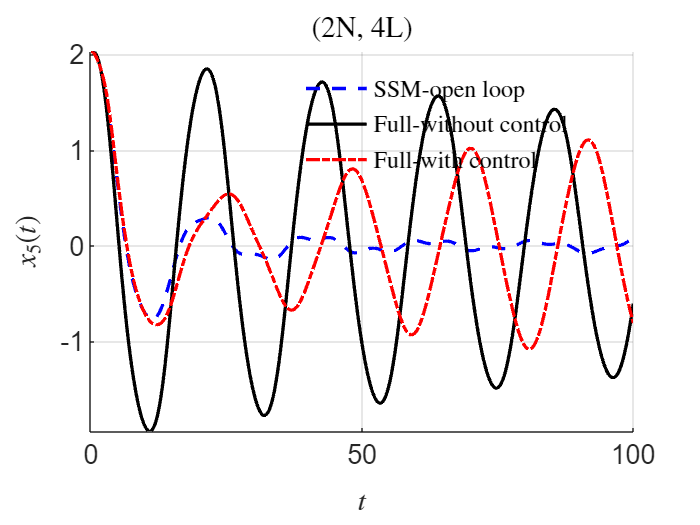

% displacement field
figure; hold on
plot(traj.time, traj.zt(2,:),'b--','DisplayName','SSM-open loop','LineWidth',2);
plot(tfullwoNL, xfullwoNL(:,2),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot(tfullwc1, xfullwc1(:,2),'r-.','DisplayName', 'Full-with control','LineWidth',2);
legend('show','Interpreter',"latex",Location="northeast"); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$x_{',num2str(outdof(2)),'}(t)$');
ylabel(zk,'Interpreter','latex');
title('(2N, 4L)','Interpreter',"latex")
set(gca,'FontSize',16);
grid on, axis tight

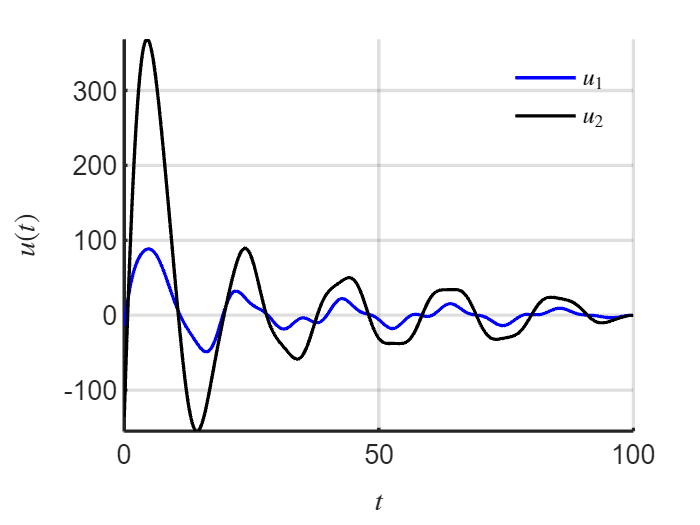


%  control input
figure; hold on;
plot(traj.time,traj.ut(1,:),'b-','DisplayName','SSM-open-control','DisplayName','$u_1$','LineWidth',2);
plot(traj.time,traj.ut(2,:),'k-','DisplayName','SSM-open-control','DisplayName','$u_2$','LineWidth',2);
legend('show','Interpreter','latex'); legend boxoff
xlabel('$t$','Interpreter',"latex")
ylabel('$u(t)$','Interpreter','latex')
set(gca,'FontSize',16); grid on, axis tight
set(gca, 'LineWidth', 2);

## Closed loop control with 2 receding horizons

t0 = 0;
t1 = tf/5; % 20s
t2 = tf;   % 100s

**Time interval - 1**

om = 2*pi/t1;
tspan1 = linspace(t0,t1,nsteps);
traj_closed1 = LQR_closed_loop(DS,z0,'linear',tspan1,auData,W_0,modes,1:4,cont);

pl
   2.4461 - 0.0013i
   2.4461 + 0.0013i
p0
   2.4461 - 0.0013i
   2.4461 + 0.0013i
Time for backward simulation of Riccati ODE is 2.894480e-02
Time for backward simulation of compensated ODE is 8.951390e-02
历时 0.066981 秒。
Time for forward simulation of ODEs for modal coordinates is 6.885800e-02


ufun = @(t) transpose(interp1(traj_closed1.time,traj_closed1.ut',t));
set(DS,'u',ufun);
[tfullwc1, xfullwc1,xf,~] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);
xf  = xf'; % initial for next interval

**Time interval - 2**

tspan2 = linspace(t1,t2,nsteps);
traj_closed2 = LQR_closed_loop(DS,xf,'linear',tspan2,auData,W_0,modes,1:4,cont);

pl
   0.5689 - 0.4723i
   0.5689 + 0.4723i
p0
   0.5689 - 0.4723i
   0.5689 + 0.4723i
Time for backward simulation of Riccati ODE is 2.983440e-02
Time for backward simulation of compensated ODE is 2.789213e-01
历时 0.348969 秒。
Time for forward simulation of ODEs for modal coordinates is 3.505458e-01


om = 2*pi/(t2-t1);
ufun = @(t) transpose(interp1(traj_closed2.time,traj_closed2.ut',t));
set(DS,'u',ufun);
[tfullwc2, xfullwc2,~,~] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',xf,'ts',t1);

**Plot - dof-1**

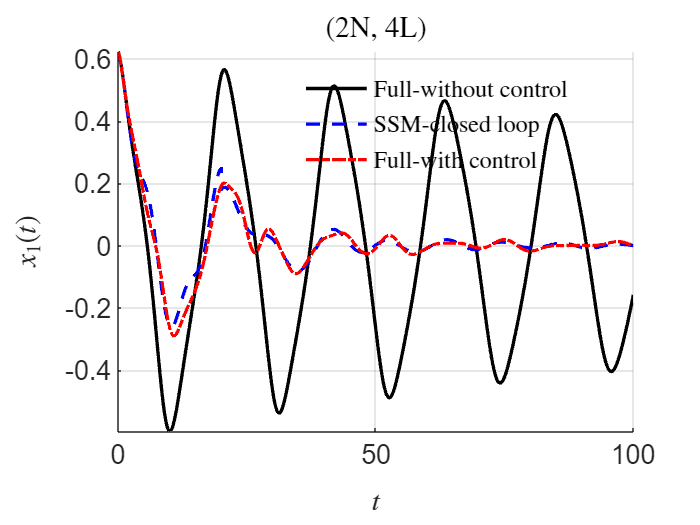

figure; hold on
plot(tfullwoNL, xfullwoNL(:,1),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot([traj_closed1.time, traj_closed2.time], [traj_closed1.zt(1,:),traj_closed2.zt(1,:)],...
                                             'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot([tfullwc1; tfullwc2], [xfullwc1(:,1); xfullwc2(:,1)],...
                                             'r-.','DisplayName', 'Full-with control','LineWidth',2);
legend('show','Interpreter',"latex",Location="northeast"); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$x_{',num2str(outdof(1)),'}(t)$');
ylabel(zk,'Interpreter','latex');
title('(2N, 4L)','Interpreter',"latex")
set(gca,'FontSize',16);
grid on, axis tight

**Plot - dof-5**

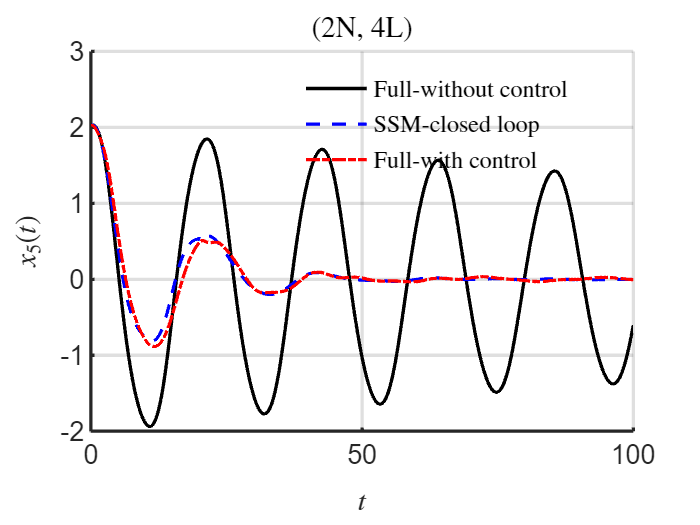

figure; hold on
plot(tfullwoNL, xfullwoNL(:,2),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot([traj_closed1.time, traj_closed2.time], [traj_closed1.zt(2,:),traj_closed2.zt(2,:)],...
                                             'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot([tfullwc1; tfullwc2], [xfullwc1(:,2); xfullwc2(:,2)],...
                                             'r-.','DisplayName', 'Full-with control','LineWidth',2);
legend('show','Interpreter',"latex",Location="northeast"); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$x_{',num2str(outdof(2)),'}(t)$');
ylabel(zk,'Interpreter','latex');
title('(2N, 4L)','Interpreter',"latex")
set(gca,'FontSize',16);
grid on
set(gca, 'LineWidth', 2);

**Plot - control inputs**

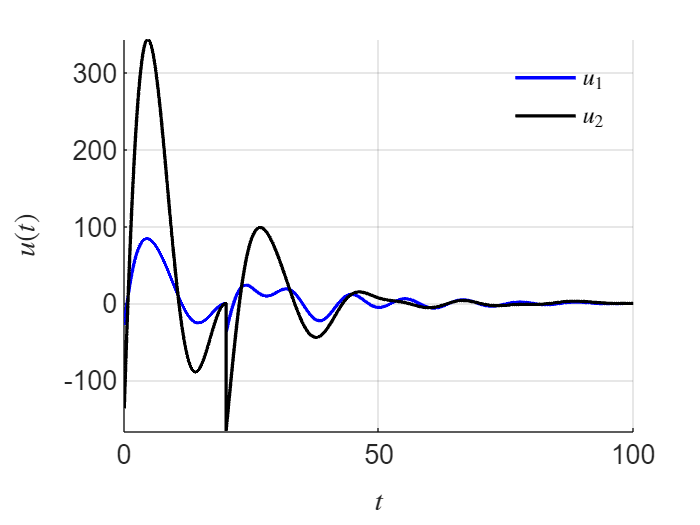

%  control input
figure; hold on;
plot([traj_closed1.time, traj_closed2.time],[traj_closed1.ut(1,:),traj_closed2.ut(1,:)],...
                                          'b-','DisplayName','SSM-open-control','DisplayName','$u_1$','LineWidth',2);
plot([traj_closed1.time, traj_closed2.time],[traj_closed1.ut(2,:),traj_closed2.ut(2,:)],...
                                          'k-','DisplayName','SSM-open-control','DisplayName','$u_2$','LineWidth',2);
legend('show','Interpreter','latex'); legend boxoff
xlabel('$t$','Interpreter',"latex")
ylabel('$u(t)$','Interpreter','latex')
set(gca,'FontSize',16); grid on, axis tight